## Define Experiment Parameters

%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "feb_2022/spatial_3muscle";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
arm_tags = [6 7 8 15 10 11 14 9]; % Tags 6 to 9 
base_tag_id = 10;

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [3 3 3 3 1 1 1 1]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 0, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 15 20 25 30 35 40 45 50 55 60];
pressure = 0;

i_test_bag = find(experiment_pressures == pressure);

## Retrieve Bag File

bag = get_tagslam_bag(experiment_name, pressure, 2);

filename = strsplit(bag.FilePath, '/');
filename = filename{end};
fprintf("Testing with bag: %s\n", filename);

Testing with bag: localized-0psi_2022-02-06-19-55-07.bag


## Extract and Plot Transformations

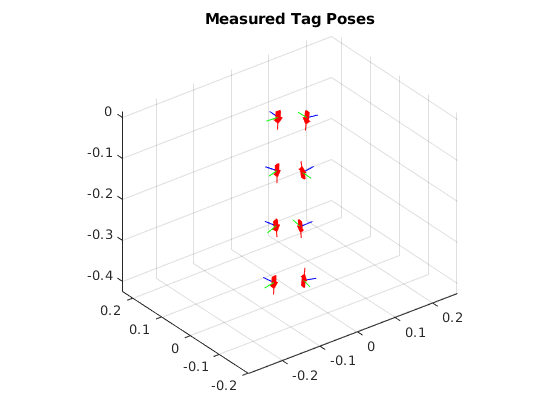

g_tags_meas = cell(size(arm_tags));
for i = 1 : length(arm_tags)
    id_tag = arm_tags(i);
    
    % Make sure that the tag we're looking for has an existing
    % transformation in the TF tree
    if ~any(bag.AvailableFrames == sprintf("tag_%d", id_tag))
        error("Tag with id %d not found in list of available frames", id_tag)
    end
    
    tform_i = getTransform(bag, "tag_" + base_tag_id, "tag_" + id_tag);
    R = quat2rotm(tform_i.Transform.Rotation.readQuaternion());
    % Apply extra 90 deg ccw rotation to correct for misplaced tags
    R = R * eul2rotm([pi/2, 0, 0], 'zyx');
    
    T_obj = tform_i.Transform.Translation;
    T = [T_obj.X; T_obj.Y; T_obj.Z];
    g_tags_meas{i} = SE3(R, T);
end

%% Plot measured tags
% First: I accidentally left the tags upside down - let's flip them around
%g_tags_meas = cellfun(@(g_tag) g_tag * SE3(eul2rotm([0, 0, pi], 'xyz'), [0;0;0]), g_tags_meas, ...
%    'UniformOutput', false);

% Base muscle pose: pointing down, located at 0,0,0:
% The neutral pose is where the main contracting muscle will be. This is
% our "origin"
g_default_muscle_original = SE3(eul2rotm([0, pi/2, 0], 'xyz'), [0 0 0]);
g_default_muscle = SE3(eul2rotm([0, pi/2 + deg2rad(7), 0], 'xyz'), [0 0 0]); % Frame corresponding to a muscle at the origin, pointing down
%g_default_muscle = eye(4);

% The default tag - the tag at the base of the default muscle - will
% actually be offset from the default muscle pose by a
% right-multiplication, corresponding to being offset in the tag-body Z
% direction.
g_tag_offset_right = SE3(eye(3), [0; 0; 0.788 * 0.0254]);
offsets = repelem({g_tag_offset_right}, length(arm_tags));
g_default_tag = g_default_muscle * g_tag_offset_right;

% Transform all tag measurements so that the base muscle is at 0,0,0, and
% the base tag is offset by a right-transformation from that base muscle
% position. These offsets and poses are defined above.
g_base_tag = g_tags_meas{arm_tags == base_tag_id};
g_tag_shift = g_default_tag * inv(g_base_tag);

% Apply the offset to each pose in the cell array
g_tags_meas = cellfun(@(g_tag) g_tag_shift * g_tag, g_tags_meas, ...
    'UniformOutput', false);

% Plot
fig = figure();
ax = axes(fig);
grid on
axis equal

plot_options = struct();
plot_options.framesize = 0.03;
plot_options.MeshFilePath = "tf_frame.stl";
[gh_tforms, T_tforms, quat_tforms] = plotTransformsSE_n(g_tags_meas, ax, plot_options);
title("Measured Tag Poses")

## Create Arm Objects

% Parameterize the arm
rho = 0.75 * 0.0254; % M, Radius
muscle_angle = 0;

%% Construct pose matrices
% Transformations from world frame to each muscle

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_muscles = Arm3D.generate_g_muscles(rho, g_default_muscle_original, 3, muscle_angle);

% Set position of first muscle to actually be at the origin
% We want to shift *everything* uniformly regardless of its pose, therefore
% it'll be a left-action:
% g_shift * g_1 = g_neutral
% Therefore g_shift = g_neutral * inv(g_1)
% Additionally, we rotate by a global 180deg so that all 3 muscles are
% aligned correctly
g_muscle_shift = g_default_muscle_original * inv(g_muscles{1});

% Then left-apply g_shift to all transformations
g_o = g_muscle_shift * g_default_muscle_original;
g_muscles = cellfun(@(g_muscle) g_muscle_shift * g_muscle, g_muscles, 'uniformoutput', false);

% ===================

model_arm =  Arm3D(g_o, g_muscles, contraction_fit(0), 'plot_unstrained', false);
model_arm.n_spacers = 0;
fit_arm = copy(model_arm);

% Initialzie model arm:
psi = experiment_pressures(i_test_bag);
v_l = contraction_fit([psi; 0; 0]);
h_o_model = model_arm.mat_N * v_l;

% Fit curvature
warning('off', 'MATLAB:logm:nonPosRealEig') % Surpress matrix log warning
% TODO: Implement analytic SE3 logm?
[h_o_fit, g_tags_fit] = ...
    curve_fit_3d(model_arm, g_tags_meas, t_tags, muscle_ids, ...
        init_val=h_o_model * 1.5, ... % Multiply by 1.5 so we don't just fit to the model solution
        offset=offsets);

## Initialize Plotting

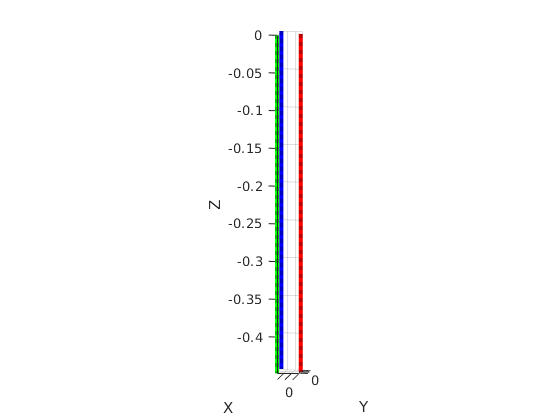

% Create figure
fig = figure();
ax = axes(fig);
grid on
axis equal

% Set plotting parameters
line_options_muscles = struct("LineWidth", 3);

f_arm_initialize_plotting = @(arm) arm.initialize_plotting(ax, "line_options_muscles", line_options_muscles);

f_arm_initialize_plotting(model_arm);
f_arm_initialize_plotting(fit_arm);

% Darken plotting colors in model arm
for i = 1 : length(model_arm.muscles)
    color_current = model_arm.muscles(i).color;
    model_arm.muscles(i).color = hsv2rgb(rgb2hsv(color_current) .* [1, 1, 0.75]);
    model_arm.muscles(i).lh.LineStyle = ":";
end

% Bring solid line (Fitted muscle curves) to the back
for i = 1 : length(fit_arm.muscles)
    uistack(fit_arm.muscles(i).lh, "bottom");
end

## Curve Fitting and Plotting

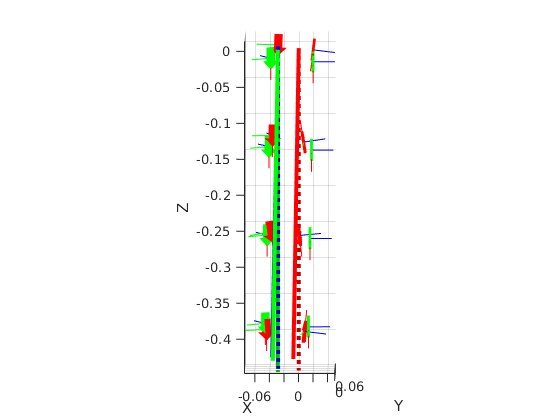

model_arm.update_arm(v_l, h_o_model);
%fit_arm.update_arm(v_l, h_o_fit .* [1 0 0 1 1 1]');
fit_arm.update_arm(v_l, h_o_fit);

plotTransformsSE_n(g_tags_meas, ax, plot_options);
plot_options.MeshColor = "green";
plotTransformsSE_n(g_tags_fit, ax, plot_options);

view([0.683 7.896])